# **Reliability Metric for Measuring Zero Stability**

**Description:** In this example, we estimate the stability of two Huffman BMOCZ zero patterns and show that the estimated stabilities are consistent with polynomial perturbation analysis.

The example illustrates our proposed reliability metric for measuring zero stability. The following functions are used:

- 
$$\texttt{jbmoczMessageToPoly()}$$


- 
$$\texttt{perturbPoly()}$$


- 
$$\texttt{estimateZeroStability()}$$


**Before starting:** ensure that your working directory is the "\examples" folder.

Add the "\functions" folder to your MATLAB path.

clear; close all; clc;

% Get current path and parent directory
currentFolder = pwd;
parentFolder = fileparts(currentFolder);

% Add functions to current path
addpath(strcat(parentFolder, '\functions'))

Set the Huffman BMOCZ zero constellation parameters.

K = 16;
R = sqrt(1 + sin(pi/K));

Generate Huffman polynomials corresponding to the all 1s and all 0s messages using $\texttt{jbmoczMessageToPoly()}$ with $\zeta=1$.

Perturb the polynomials with $\texttt{Nsim}$ independent AWGN realizations (at an $E_\mathrm{b}/N_0$ of your choosing) using $\texttt{perturbPoly()}$.

Save the perturbed zeros.

% Generate polynomials for the all 1s and all 0s messages
messageSequences = [ones(K, 1), zeros(K, 1)];
[huffmanPolys, huffmanZeros] = jbmoczMessageToPoly(messageSequences, R, 1, K+1);

% Perturbation parameters 
Nsim = 1000;  % Number of AWGN realizations
EbN0 = 8;     % dB

% Perturb the polynomials
perturbedZeros = ones(K, Nsim, 2);
for p = 1:2
    perturbedZeros(:, :, p) = perturbPoly(huffmanPolys(:, p), Nsim, EbN0);
end

% Save the perturbed zeros
perturbedOuterZeros = perturbedZeros(:, :, 1);
perturbedInnerZeros = perturbedZeros(:, :, 2);

Estimate the stability of the all 1s and all 0s zero patterns using $\texttt{estimateStability()}$with a DFT size of $\texttt{Nover}$.

Plot the zeros of the perturbed polynomials and display the estimated stability of each zero pattern.

**Note:** you must choose $\texttt{Nover}>=\texttt{K}+1$, and a larger power of 2 is ideal, e.g., 1024.

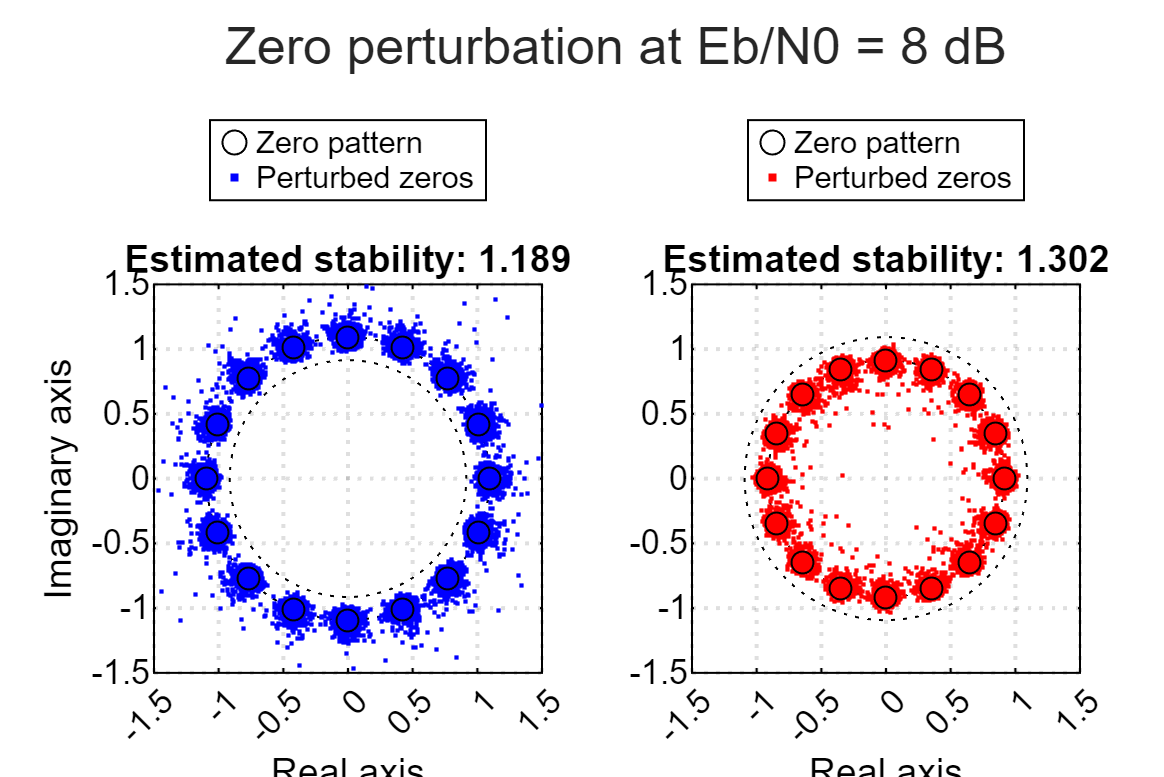

Nover = 1024;  % DFT size

% Estimate the stability of each zero pattern
Cmean = estimateZeroStability(huffmanZeros, 1, Nover);

% Plot the perturbed zero patterns
theta = linspace(0, 2*pi, 100);
Router = R * exp(1j*theta); Rinner = 1/R * exp(1j*theta);

sz = 10;

f1 = figure(1);

tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile
grid on; box on; hold on; axis square;
ax = gca; ax.GridLineStyle = ':'; ax.GridLineWidth = 1;

plot(real(Rinner), imag(Rinner), 'k:')
plot(real(Router), imag(Router), 'k:')

s1 = scatter(real(huffmanZeros(:, 1)), imag(huffmanZeros(:, 1)), 3*sz, 'ko');
s2 = scatter(real(perturbedOuterZeros(:)), imag(perturbedOuterZeros(:)), sz, 'b.');

uistack(s1, 'top')

xlabel('Real axis')
ylabel('Imaginary axis')

xticks(-1.5:0.5:1.5)
axis([-1.5, 1.5, -1.5, 1.5])

lgd = legend([s1, s2], {'Zero pattern', 'Perturbed zeros'});
lgd.Location = 'northoutside';

title(['Estimated stability: ', num2str(Cmean(1), '%.3f')])

nexttile
grid on; box on; hold on; axis square;
ax = gca; ax.GridLineStyle = ':'; ax.GridLineWidth = 1;

plot(real(Rinner), imag(Rinner), 'k:')
plot(real(Router), imag(Router), 'k:')

s1 = scatter(real(huffmanZeros(:, 2)), imag(huffmanZeros(:, 2)), 3*sz, 'ko');
s2 = scatter(real(perturbedInnerZeros(:)), imag(perturbedInnerZeros(:)), sz, 'r.');

uistack(s1, 'top')

xlabel('Real axis')

xticks(-1.5:0.5:1.5)
axis([-1.5, 1.5, -1.5, 1.5])

lgd = legend([s1, s2], {'Zero pattern', 'Perturbed zeros'});
lgd.Location = 'northoutside';

title(['Estimated stability: ', num2str(Cmean(2), '%.3f')])
sgtitle(['Zero perturbation at Eb/N0 = ', num2str(EbN0, '%d'), ' dB'])

set(f1, 'Position', [50 50 1200 800])  

Observe that the zeros on the inner radius are slightly more stable than those on the outer radius, a result reflected in the estimated stability of the zero patterns.